clc, clear, close all
datetime('today')

ans = datetime
   29-May-2023


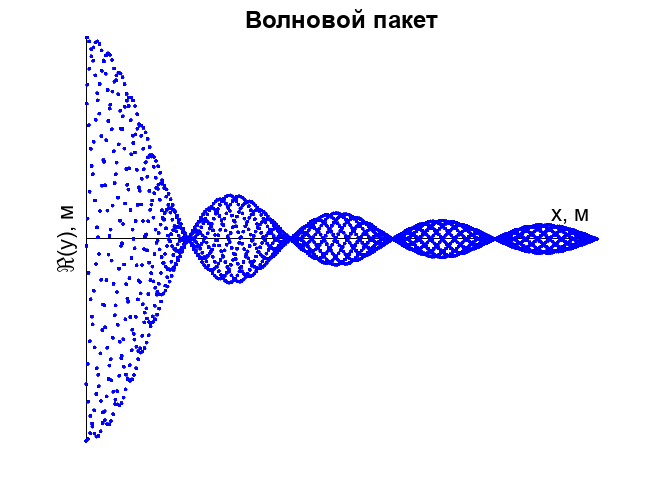


A = 0.5;
lambda = 100;
dk = 0.01 * pi;
k0 = 2 * pi / lambda;
w = pi;
x = linspace(0, 500, 2000);
t = linspace(1, 500, 2000);

h = figure(1);
hold on;
ax = gca;

ax.XAxisLocation = 'origin';
ax.XColor = "k";
xlabel('x, м');
set(ax,'xticklabel',[]);
set(gca,'XTick',[]);

ax.YColor = "k";
ylabel('\Re{(y)}, м');
set(ax,'yticklabel',[]);
set(gca,'YTick',[]);

title('Волновой пакет', 'FontSize', 12);

for i = 1 : numel(x)
    fun = @(k) exp(1i * (k * x(i) - w * t(i)));
    y = (A / dk) * integral(fun, k0  - dk, k0  + dk);
    plot(x(i), real(y), '.', 'Color', 'b');
    drawnow limitrate;
    if (~ishandle(h))
        break;
    end
end